clc;
clear;
close


Image2 = imread('shopping-mall.png');
IGray2 = rgb_to_gray(Image2);
figure;
imshow(Image2);

hold on

% get the size of the img
[m,n]=size(IGray2);



#### Draw vanishing point

% initial VanishingPoint(middle of the Picture)
vb= .5 * (m);
va =.5 * (n);

% plot(va, vb,'r*')
pos_VanishingPoint = [va vb];
roi_VanishingPoint = images.roi.Point(gca,'Position',pos_VanishingPoint,"Color",'k',"LineWidth",5);
hold on

#### Draw inner rectangle

% [x y w h]= x and y elements determine the location (top-left) and the w and h elements determine the size
pos_InnerRectangle = [va-250,vb-250,500,500];
roi_InnerRectangle = drawrectangle('Color','k','FaceAlpha', 0, ...
    'FaceSelectable',(false),'LineWidth',1,'MarkerSize',8);
roi_InnerRectangle.Position = pos_InnerRectangle

roi_InnerRectangle =   Rectangle - 属性:

         Position: [569 774 500 500]
    RotationAngle: 0
      AspectRatio: 1
            Label: ''
            Color: [0 0 0]
           Parent: [1×1 Axes]
          Visible: on
         Selected: 0

  显示 所有属性


#### Draw 4 radial lines

1. 4 edges of inner rectangle

r_top_left = [pos_InnerRectangle(1), pos_InnerRectangle(2)];
r_top_right = [pos_InnerRectangle(1) + pos_InnerRectangle(3), pos_InnerRectangle(2)];
r_bottom_left = [pos_InnerRectangle(1), pos_InnerRectangle(2)+pos_InnerRectangle(4)];
r_botton_right = [pos_InnerRectangle(1)+pos_InnerRectangle(3), pos_InnerRectangle(2)+pos_InnerRectangle(4)];


% roi_line1 = drawline('Position',[r_top_left;pos_VanishingPoint],'Color','r');
% roi_line2 = drawline('Position',[r_top_right;pos_VanishingPoint],'Color','r');
% roi_line3 = drawline('Position',[r_bottom_left;pos_VanishingPoint],'Color','r');
% roi_line4 = drawline('Position',[r_botton_right;pos_VanishingPoint],'Color','r');



#### Get Positions of vanishing point & inner rectangle

 1. position of vanishing point

addlistener(roi_VanishingPoint,'MovingROI',@(src, evt) roiChange(src,evt,'Updated_VanishingPoint'));

2. position of inner rectangle

addlistener(roi_InnerRectangle,'MovingROI',@(src, evt) roiChange(src,evt,'Updated_InnerRectangle'));

 updated vertices of inner rectangle

Updated_InnerRectangle = 'Updated_InnerRectangle.mat';
save(Updated_InnerRectangle)
load Updated_InnerRectangle.mat


% updated_top_left = [Updated_InnerRectangle(1), Updated_InnerRectangle(2)]
% updated_top_right = [Updated_InnerRectangle(1) + Updated_InnerRectangle(3), Updated_InnerRectangle(2)]
% updated_bottom_left = [Updated_InnerRectangle(1), Updated_InnerRectangle(2)+Updated_InnerRectangle(4)]
% updated_botton_right = [Updated_InnerRectangle(1)+Updated_InnerRectangle(3), Updated_InnerRectangle(2)+Updated_InnerRectangle(4)]

updated_top_left = [pos_InnerRectangle(1), pos_InnerRectangle(2)]

updated_top_left =    569   774


updated_top_right = [pos_InnerRectangle(1) + pos_InnerRectangle(3), pos_InnerRectangle(2)]

updated_top_right =         1069         774


updated_bottom_left = [pos_InnerRectangle(1), pos_InnerRectangle(2)+pos_InnerRectangle(4)]

updated_bottom_left =          569        1274


updated_botton_right = [pos_InnerRectangle(1)+pos_InnerRectangle(3), pos_InnerRectangle(2)+pos_InnerRectangle(4)]

updated_botton_right =         1069        1274


 updated position of vanishing point

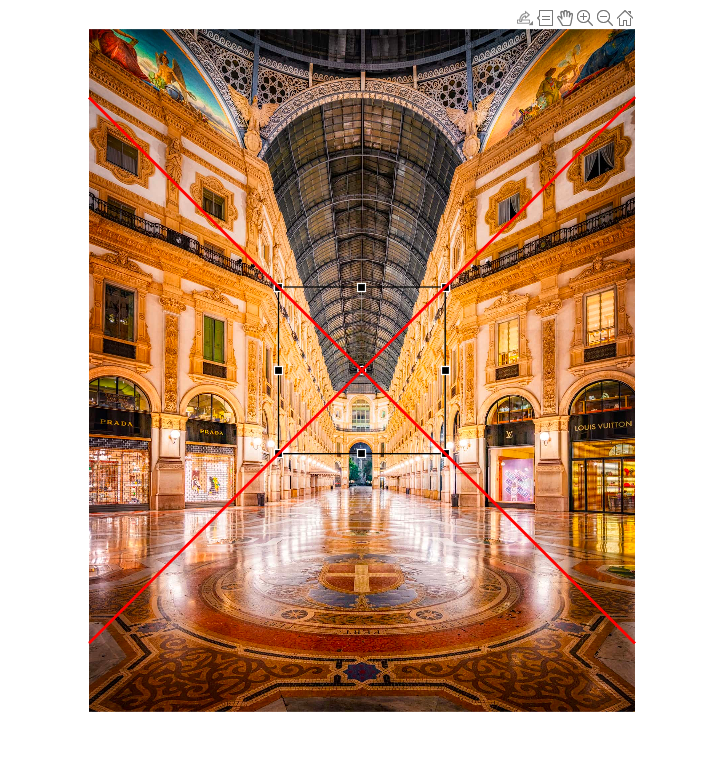

Updated_VanishingPoint = 'Updated_VanishingPoint.mat';
save(Updated_VanishingPoint)


% h = drawline('Position',[500 500;500 1500],'Color','r');

radialline_left(pos_VanishingPoint,updated_top_left,Image2);
radialline_left(pos_VanishingPoint,updated_bottom_left,Image2);

radialline_right(pos_VanishingPoint,updated_top_right,Image2);
radialline_right(pos_VanishingPoint,updated_botton_right,Image2);

function radialline_left(CenterPoint, ThroPoint, img)
% CenterPoint: radial line start point
% ThroPoint: radial line through point
% img: backgroud image

% coefficients = polyfit([x1 x2], [y1 y2], 1);
coefficients = polyfit([CenterPoint(1) ThroPoint(1)], [CenterPoint(2) ThroPoint(2)], 1);
a = coefficients (1);
b = coefficients (2);

aLine = [a,-1,b];

points = lineToBorderPoints(aLine,size(img));

line([points(1),CenterPoint(1)],[points(2),CenterPoint(2)],'Color', 'r', 'LineWidth', 2);
end

function radialline_right(CenterPoint, ThroPoint, img)
% coefficients = polyfit([x1 x2], [y1 y2], 1);
coefficients = polyfit([CenterPoint(1) ThroPoint(1)], [CenterPoint(2) ThroPoint(2)], 1);
a = coefficients (1);
b = coefficients (2);

aLine = [a,-1,b];

points = lineToBorderPoints(aLine,size(img));

line([points(3),CenterPoint(1)],[points(4),CenterPoint(2)],'Color', 'r', 'LineWidth', 2);
end

function roi = roiChange(~,evt,roi)
    assignin('base',roi,evt.CurrentPosition);

end


